# Actividad 3 (Evaluación)

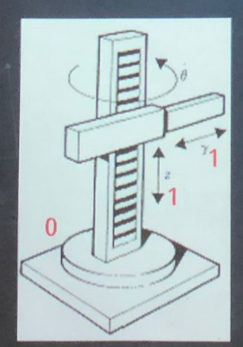

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t)  t l1 l2  

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l1, l2];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%matriz valuada en x -90
x= [1 0 0; 
    0 0 1; 
    0 -1 0];
%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; th1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1]*x;

%Articulación 2 
%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º a rededor de y1 
R(:,:,2)= [1  0  0 ;
           0  0  1;
           0  -1  0];

%Articulación 3 
%Posición de la articulación 3 respecto a 0
P(:,:,3)= [0 ; 0; l2];
%Matriz de rotación de la junta 3 respecto a 0.... -90º y1 
R(:,:,3)= [0  0  -1 ;
           0  1  0;
           1  0  0];

%creamos un vector de ceros
vector_zeros= zeros(1,3);
%inicializamos las matrices de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); vector_zeros 1]);
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); vector_zeros 1]);

%inicializamos los vectores de posicion vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%inicializamos las matrices de rotacion vistos desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);
 

for i = 1:GDL
    i_str= num2str(i);
    %locales
    %disp(strcat('Matriz de transformacion local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); vector_zeros 1]);
    %pretty (A(:,:,i));

    %globales
    try
        T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i)= A(:,:,i);% CASO ESPECIFICO cuando i=1 nos marcaria erroren try
    end
    disp(strcat('Mariz de trasformacion global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));

    %matriz de rotacion RO y el vector de translacion PO
    %de la matriz de transformacion homogenea global T(:,:,GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Mariz de trasformacion global T1


/ cos(th1(t)),  0, -sin(th1(t)),    0   \
|                                       |
| sin(th1(t)),  0,  cos(th1(t)),    0   |
|                                       |
|      0,      -1,       0,      th1(t) |
|                                       |
\      0,       0,       0,         1   /



Mariz de trasformacion global T2


/ cos(th1(t)),  sin(th1(t)),  0, -l1 sin(th1(t)) \
|                                                |
| sin(th1(t)), -cos(th1(t)),  0,  l1 cos(th1(t)) |
|                                                |
|      0,            0,      -1,      th1(t)     |
|                                                |
\      0,            0,       0,        1        /



Mariz de trasformacion global T3


/  0,  sin(th1(t)), -cos(th1(t)), -l1 sin(th1(t)) \
|                                                 |
|  0, -cos(th1(t)), -sin(th1(t)),  l1 cos(th1(t)) |
|                                                 |
| -1,       0,            0,        th1(t) - l2   |
|                                                 |
\  0,       0,            0,             1        /




%calculamos el jacobiano lineal y angular de forma analitica
%inicializacion jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if ((RP(k)==0))%|(RP(k)==1))%casos: articulacion rotacional y prismatica

        %para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%matriz de rotacion de 0 con respecto a 0 es la matriz identidad...
            Jw_a(:,k)= [0,0,1];% si no hay matriz de rotacion previa se obtiene la matriz identidad...
        end
      else
        %para las articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)= [0,0,1];%si no hay matriz de rotacion previa se obtiene la matriz ...
       end
           Jw_a(:,k)= [0,0,0];
    end
end
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analitica');
%pretty (Jv_a);
%disp('Jacobiano angular obtenido de forma analitica');
%pretty (Jw_a);

disp('Velocidad lineal obtenido mediante el jacobiano lineal');

Velocidad lineal obtenido mediante el jacobiano lineal


V=simplify (Jv_a*Qp');
pretty (V);

/     _________             \
|      d                    |
| -l1 -- th1(t) cos(th1(t)) |
|     dt                    |
|                           |
|     _________             |
|      d                    |
| -l1 -- th1(t) sin(th1(t)) |
|     dt                    |
|                           |
\             0             /



disp('Velocidad angular obtenido mediante el jacobiano angular');

Velocidad angular obtenido mediante el jacobiano angular


W=simplify (Jw_a*Qp');
pretty (W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /

